% sla_unfiltered [m]
% Sea level anomaly not-filtered not-subsampled with dac, ocean_tide and lwe correction applied
% sea_surface_height_above_sea_level
% sla_filtered [m]
% Sea level anomaly filtered not-subsampled with dac, ocean_tide and lwe correction applied
% sea_surface_height_above_sea_level
% mdt [m]
% Mean dynamic topography
% sea_surface_height_above_geoid
% dac [m]
% Dynamic Atmospheric Correction
% -
% ocean_tide [m]
% Ocean tide model
% -
% internal_tide [m]
% Internal Tide signal: coherent mode M2/K1/O1/S2
% -
% lwe [m]
% Long wavelength error
% -
% Coordinate variables name in the NetCDF file and Unit: Long_name & Standard_name
% time [days since 1950-01-01 00:00:00]
% Time of measurement
% time
% longitude [degrees_east]
% Longitude of measurement (theoretical position for repetitive orbits)
% longitude
% latitude [degrees_north]
% Latitude of measurement (theoretical position for repetitive orbits)
% latitude
% Other useful variables name in the NetCDF file and Unit: Long_name & Standard_name
% Flag [0,1]
% Data origin
% -
% cycle [1]
% Cycle the measurement belongs to
% -
% track [1]
% Track in cycle the measurement belongs to

% Import the csv file and sort based on time
eddyData = readtable('G:\My Drive\AlongTrack\MyCode\along_track_data_for_eddy_132461.csv', 'ReadVariableNames', true);
eddyData = sortrows(eddyData, 'time', 'ascend');
SingleEddy = table2struct(eddyData,"ToScalar",true);
use SingleEddy
%%
% Import the csv file and sort based on time
%Define file names
[eddyfile,argofile,drifterfile] = OceanEddies.findSSHEddyDataFiles(dir='G:\My Drive\AlongTrack\MyCode\');
%[eddyfile,argofile,drifterfile] = OceanEddies.findDrifterEddyDataFiles(dir='./example-drifter-eddy-data');

%Load eddy and argo data
%make sure these files are on your Matlab search path
eddy = OceanEddies.structFromSSHEddyFile(eddyfile);
lono_eddy=eddy.longitude{1};
lato_eddy=eddy.latitude{1};
date_eddy=datenum(eddy.date{1});


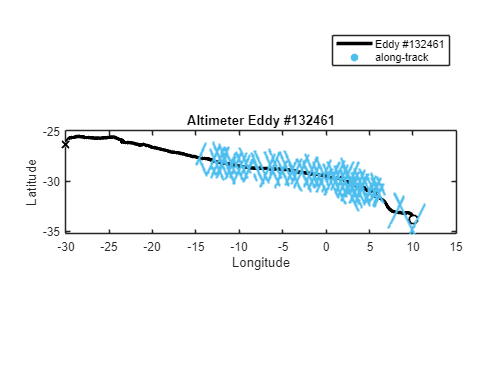

figure;hold on
h(1)=plot(eddy.longitude{1},eddy.latitude{1},'LineWidth',3,'Color',0*[1 1 1]);
plot(eddy.longitude{1}(1),eddy.latitude{1}(1),'ko','markersize',8,'markerfacecolor','k')
plot(eddy.longitude{1}(1),eddy.latitude{1}(1),'wo','markersize',5,'markerfacecolor','w')
plot(eddy.longitude{1}(end),eddy.latitude{1}(end),'wx','markersize',10,'linewidth',2)
plot(eddy.longitude{1}(end),eddy.latitude{1}(end),'kx','markersize',8,'linewidth',1.5)
h(2)=scatter(longitude, latitude,2,'MarkerFaceColor','flat');
xlabel('Longitude'), ylabel('Latitude'), box on
title(['Altimeter Eddy #' int2str(eddy.eddy_id{1}(1))],'interpreter','tex')

%set aspect ratio correctly for midpoint of y-axes limits
set(gca,'dataaspectratio',[1 cosd(mean(get(gca,'ylim'))) 1])

%for optional legend
if true %set to false is no legend is desired
    clear str
    str{1}=['Eddy #' int2str(eddy.eddy_id{1}(1))];
    str{2}=['along-track'];
    legend(h,str,'location','best','interpreter','tex')
end

% plot(eddy.date{1},eddy.amplitude{1},'k','linewidth',2), hold on
% plot(eddy.date{1},eddy.speed_radius{1},'k','linewidth',2), hold on
Totaltracks=length(unique(track))

Totaltracks = 39

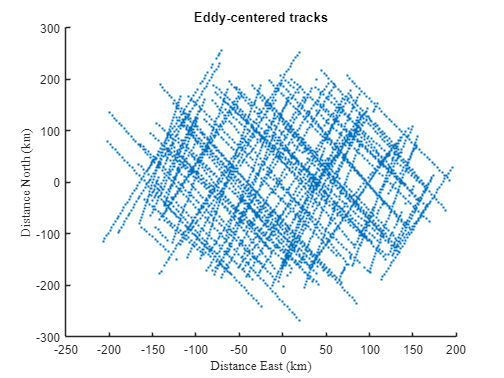

timet=datenum(time);

%Convert these latitudes and longitudes back to x and y
% longitude = deg180(longitude-lono_eddy(1)) + lono_eddy(1);%avoids unwrapping issues
[xt, yt] = latlon2xy(latitude, longitude, lato_eddy(1), lono_eddy(1));
% lono_eddy = deg180(lono_eddy-lono_eddy(1)) + lono_eddy(1);%avoids unwrapping issues
[xo, yo] = latlon2xy(lato_eddy, lono_eddy, lato_eddy(1), lono_eddy(1));

clearvars xEt yEt
for i=1:length(timet)
        match_idx=find(date_eddy==datenum(dateshift(time(i), 'start', 'day')));
        xEt(i)=xt(i)-xo(match_idx);
        yEt(i)=yt(i)-yo(match_idx);
end

figure;
scatter(xEt,yEt,2,'MarkerFaceColor','flat')
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
title('Eddy-centered tracks')


ssht=sla_filtered/10; %what unit is sla_filtered? max(sla_filtered)=32767
window_size=21;
outliers=isoutlier(ssht,'movmean',window_size);
ssht(outliers) = NaN;
fprintf('Number of outliers detected: %d\n', sum(outliers));

Number of outliers detected: 3


fprintf('Percentage of outliers: %.2f%%\n', 100 * sum(outliers) / numel(ssht));

Percentage of outliers: 0.05%


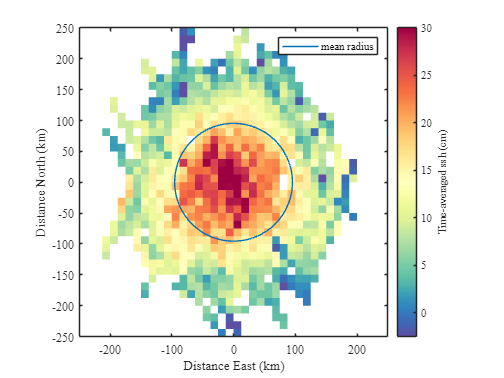

% 2D statistisc on defined bins
[mz, xmid, ymid, numz, stdz] = twodstats(xEt, yEt, ssht, -250:12.5:250, -250:12.5:250);

% mean ssh 2D
figure;hold on
jpcolor(xmid, ymid, mz)
r=mean(eddy.speed_radius{1});
th = 0:pi/50:2*pi;
plot(r * cos(th),r*sin(th))
legend('','mean radius')
% jpcolor(xEbin, yEbin, AvgsshAccumBin)
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Time-averaged ssh (cm)';
xlim([-250, 250]), ylim([-250, 250]);
clim([-2.5, 30])

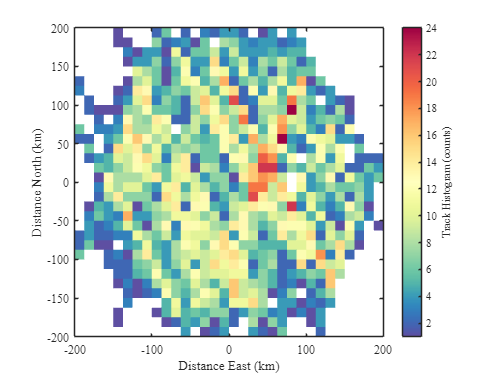

% plot 2D temporal std
% figure;
% jpcolor(xmid, ymid, stdz);
% % jpcolor(xEbin, yEbin, stdTempD);
% shading flat
% % hold on
% % contour(xE,yE,stdTemp2D,[0:0.1:2],'k')
% axis equal
% xlabel('Distance East (km)', 'FontName', 'times')
% ylabel('Distance North (km)', 'FontName', 'times')
% set(gca, 'fontname', 'times')
% colormap(brewermap([], '-Spectral'))
% c = colorbar('EastOutside');
% c.Label.String = 'Temporal std (cm)';
% xlim([-200, 200]), ylim([-200, 200]); clim([0, 2])
% 2D track counts histogram
figure;
numz(numz == 0) = nan;
jpcolor(xmid, ymid, numz) %
clim(round([min(numz(:)), max(numz(:))]))
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Track Histogram (counts)';
xlim([-200, 200]), ylim([-200, 200]);

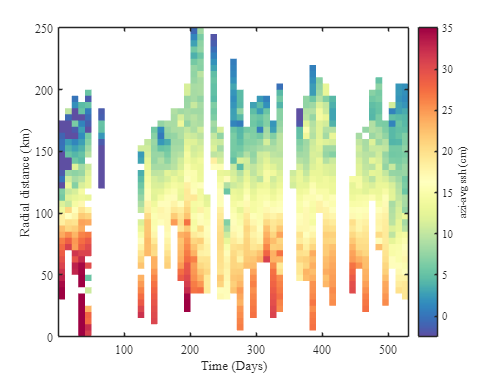

%%
tmat = timet-timet(1);
[mz_rt, rmid, tmid, numz_rt, stdz_rt] = twodstats(sqrt(xEt.^2+yEt.^2), tmat', ssht, (0:5:250), 0.5+min(tmat):10:max(tmat)+0.5);

figure;
hold on; 
jpcolor(tmid, rmid, mz_rt'), ylim([0, 250]) %mz_rt'./vmean(mz_rt,2)'
xlabel('Time (Days)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'azi-avg ssh (cm)';
set(gca, 'fontname', 'times')
clim([-2.5, 35])


tbin = [min(timet, [], "all") - .5:1:max(timet, [], "all") + 0.5]'; %tbin for radialStatisticsFromScatter has to be per days for 'azimuthal'
rbin = [-5 / 2:5:250]';
datetime(tbin(1),"ConvertFrom","datenum")

ans = datetime
   30-Dec-2011 00:00:38


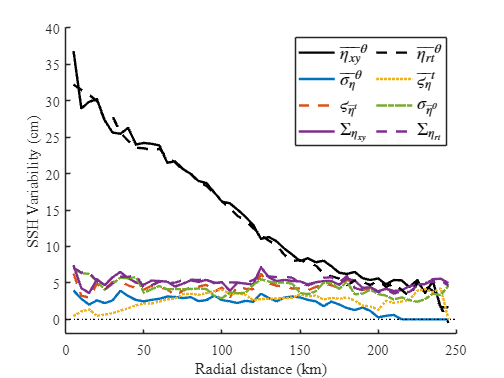

%% Compute statistics
[mzxy, rmid, numz, stdAziAvgTemp, AvgAziStdTemp] = radialStatisticsFromScatter(xEt', yEt', timet, ssht, rbin, tbin, firstAverage = 'temporal');
[mzrt, rmid, numz, stdTempAvgAzi, AvgTempStdAzi] = radialStatisticsFromScatter(xEt', yEt', timet, ssht, rbin, tbin, firstAverage = 'azimuthal');
% Std Total
stdTotalxy = sqrt(stdAziAvgTemp.^2+AvgAziStdTemp.^2);
stdTotalrt = sqrt(stdTempAvgAzi.^2+AvgTempStdAzi.^2);

%plot profile
%2k : linewidth 2, k black.
%captial A-Z in rainbow order
%T:blue, U:orange, V:yellow, X:green,W:purple
figure; hold on
h = plot(rmid, [mzxy, AvgAziStdTemp, stdAziAvgTemp, stdTotalxy, mzrt, AvgTempStdAzi, stdTempAvgAzi, stdTotalrt]);
linestyle 2k 2T 2U-- 2W 2k-- 2V: 2X-. 2W--
hlines(0, 'k:')

xlabel('Radial distance (km)', 'FontName', 'times')
ylabel('SSH Variability (cm)', 'FontName', 'times')
set(gca, 'fontname', 'times')
lg = legend(h, '$\overline{\eta_{xy}}^\theta$', '$\overline{\sigma_\eta}^\theta$', '$\varsigma_{\overline{\eta}^t}$', '$\Sigma_{\eta_{xy}}$', '$\overline{\eta_{rt}}^\theta$', '$\overline{\varsigma_\eta}^t$', '$\sigma_{\overline{\eta}^\theta}$', '$\Sigma_{\eta_{rt}}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical', 'NumColumns', 2)
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 40])